# ADC performance requirements

Consider, for example, a reciever like GSM standard, which has narrowband 200 kHz bandwidth with 14 bit 65 MSPS ADC, such as the AD6644. This ADC has a 2.2 volt peak to peak input range, typical SNR of 74.5 dB, 14 bit.

Let's calculate sensitivity of the reciever

% boltzmann’s constant
k = 1.38 * 10^(-23);    % J/K 
% temperature
T = 300;    % K
% bandwidth
BW = 200*10^3; %Hz
% noise Fugure of reciever
NF_rec = 5;  % dB 
% gain of reciever
Gain_rec = 25;   % dB
% datasheet SNR of ADC
SNR_typ = 74.5;    % dB
% peak to peak input range of ADC
AMP = 2.2;
% ADC samplerate
Fs = 65*10^6;   % SPS
% ADC bit error
BER = 5;    % dB

## Antenna part

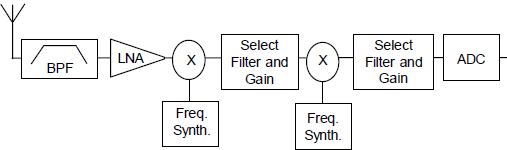

Figure 1. Typical Single-Carrier Receiver

Available noise power from the antenna:


$$P_a \;=\;k*T*\textrm{BW},\;\;\;\textrm{watts}$$


 - where k is Boltzmann's constant, T is room temperature in K, BW is bandwidth.

Fundamental noise floor of the reciever:


$$\textrm{Noise}\;\textrm{floor}=10*\lg \left(\frac{P_a }{1\textrm{mW}}\right),\;\;\frac{\textrm{dBm}}{\textrm{Hz}}$$


% available noise power from the antenna
P_a = k*T*BW;   % watts
% fundamental noise floor of the reciever
N_floor_rec = 10*log10(P_a/10^(-3));    % dBm/Hz

Noise before ADC:


$${\textrm{ADC}}_{\textrm{noise}} ={\textrm{NF}}_{\textrm{reciever}} +{\textrm{Gain}}_{\textrm{reciever}} +\textrm{Noise}\;\textrm{floor},\;\;\textrm{dBm}$$


% noise at input of ADC
ADC_input_noise = N_floor_rec + NF_rec + Gain_rec;  % dBm

## ADC part

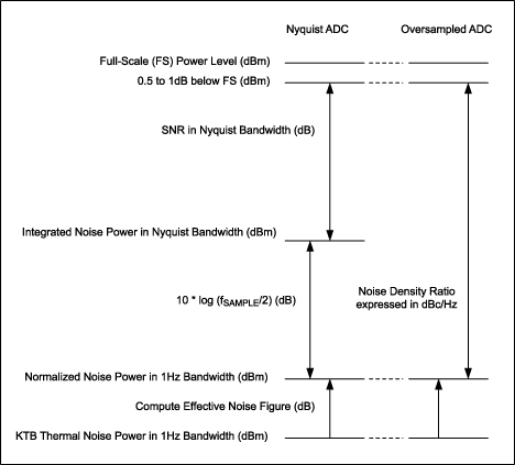

Figure 2. Compare effective noise figure for Nyquist ADC and oversampling ADC.

Root Mean Square full-scale value:


$${\textrm{RMS}}_{\textrm{full}-\textrm{scale}} =\frac{V_{\textrm{peak}\;\textrm{to}\;\textrm{peak}} }{2*\sqrt{2}},\;\textrm{volts}$$


Signal-to-Noise Ratio of ADC:


$${\textrm{SNR}}_{\textrm{effective}} ={\left({\textrm{RMS}}_{\textrm{full}-\textrm{scale}} *{10}^{\left(-\frac{{\textrm{SNR}}_{\textrm{typical}} }{20}\right)} \right)}^2 ,\;\;\textrm{dBm}$$


Digital filtering has the effect of removing all unwanted noise and spurious signals, therefore SNR of the ADC may be greatly improved:


$$\textrm{Process}\;\textrm{gain}=10*\lg \left(\frac{F_s }{2*\textrm{BW}}\right),\;\textrm{dB}$$


% root Mean Square full-scale value
rms_full = AMP/(2*sqrt(2)); % volts 
% all noises within the ADC, thermal and quantization (volts^2).
V_noise_v = (rms_full*10^(-SNR_typ/20))^2; % volts^2
% converting volts to dBm (assuming 200 ohm input impedance into the ADC)
V_noise_dBm = 10*log10(V_noise_v/200/0.001);    % dBm
SNR_effective = V_noise_dBm     % dynamic range

SNR_effective = -69.6927

% the process gain due to oversampling for these conditions is given by
% it is increased after appropriate digital filtering. 
Process_gain = 10*log10(Fs/(2*BW));   % dB
% processing gain of a 200 kHz channel improves the effective SNR to –91.8 
% dBm for the ADC (oversampling)
SNR_proc_gain = SNR_effective - Process_gain;   % dB

## Overall system noise

The overall system noise can be determined by combining the front-end noise of the receiver and the ADC noise:

$\textrm{Overall}\;\textrm{system}\;\textrm{noise}={\textrm{ADC}}_{\textrm{noise}} +{\textrm{SNR}}_{\textrm{process}\;\textrm{gain}}$, watts

Syst_noise = 0.001*10^(ADC_input_noise/10) + 0.001*10^(SNR_proc_gain/10)   % watts

Syst_noise = 1.4885e-12

## Sensetivity of system

Fullscale input power of the ADC:


$$\mathrm{Signal}\;\mathrm{power}=10*\mathrm{log}\left(\frac{V_{\mathrm{rms}}^2 }{R_{\mathrm{in}} }\right)+30\;\mathrm{dB}$$


% full scale input power in dBm
ADC_full_scale = 10*log10(rms_full^2/200) + 30   % dBm 

ADC_full_scale = 4.8073

% full scale input power in watts
ADC_power_full = 0.001*10^(ADC_full_scale/10);  % watts 

ADC_power_full = 0.0030

% maximum SNR in a 200 kHz bandwidth (we take into account the receiver 
% noise and normalized noise power in 200 kHz bandwidth of ADC)

% maximum SNR in a your bandwidth is
SNR_max = -10*log10(ADC_power_full/Syst_noise);   % dB
% referred sensitivity at the antenna of
Sen = SNR_max + BER + Signal_power - Gain_rec   % dBm

Sen = -108.2725

% noise figure of ADC
NF_ADC = -N_floor_rec + SNR_effective - Process_gain    % dB

NF_ADC = 29.0184